例2-2 画图法 计算用一阶惯性+迟滞拟合的参数

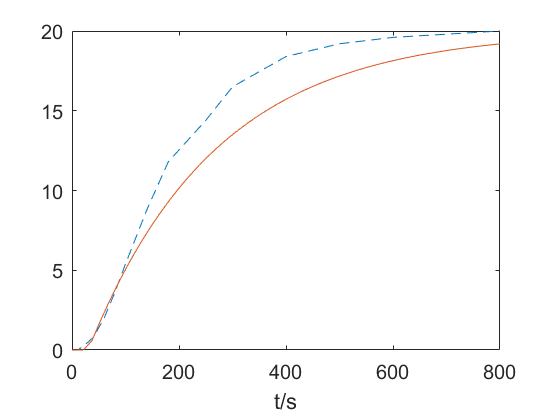

figure;
% 描点
t=[0 10 20 40 60 80 100 140 180 250 300 400 500 600 700 800];
h=[0 0 0.2 0.8 2.0 3.6 5.4 8.8 11.8 14.4 16.5 18.4 19.2 19.6 19.8 20];
plot(t,h,'--');xlabel('t/s');
hold on 
% 画图法计算用一阶惯性+迟滞拟合的参数，T=240，τ=30
% simulink仿真
out=sim('ex2_2',800);
t0=[0
3.15544362088405e-30
1.00475457260383e-05
6.02852743562299e-05
0.000311473917507188
0.00156741713326198
0.00784713321203593
0.0392457136059057
0.196238615575254
0.981203125421998
4.90602567465572
20.9060256746557
36.9060256746557
52.9060256746557
68.9060256746557
84.9060256746557
100.906025674656
116.906025674656
132.906025674656
148.906025674656
164.906025674656
180.906025674656
196.906025674656
212.906025674656
228.906025674656
244.906025674656
260.906025674656
276.906025674656
292.906025674656
308.906025674656
324.906025674656
340.906025674656
356.906025674656
372.906025674656
388.906025674656
404.906025674656
420.906025674656
436.906025674656
452.906025674656
468.906025674656
484.906025674656
500.906025674656
516.906025674656
532.906025674656
548.906025674656
564.906025674656
580.906025674656
596.906025674656
612.906025674656
628.906025674656
644.906025674656
660.906025674656
676.906025674656
692.906025674656
708.906025674656
724.906025674656
740.906025674656
756.906025674656
772.906025674656
788.906025674656
800];
h0=[0
0
0
0
0
0
0
0
0
0
0
0
0.562655256714643
1.81622822169256
2.98895448670821
4.08604809919034
5.11238683692895
6.07253389511818
6.97075817473628
7.81105326246694
8.59715518654819
9.33255902749307
10.0205344575349
10.6641402778867
11.2662380184492
11.8295046604326
12.3564445384578
12.8494004750555
13.3105641970680
13.7419860802657
14.1455842655037
14.5231531869501
14.8763715503038
15.2068097964717
15.5159370838917
15.8051278205449
16.0756677746979
16.3287597915450
16.5655291411676
16.7870285215871
16.9942427391553
17.1880930870935
17.3694414416455
17.5390940940574
17.6978053354223
17.8462808103263
17.9851806542086
18.1151224283839
18.2366838657755
18.3504054395690
18.4567927662045
18.5563188533936
18.6494262031544
18.7365287792158
18.8180138475377
18.8942436981306
18.9655572558303
19.0322715871875
19.0946833101756
19.1530699129805
19.1912505107750];
plot(t0,h0);

例2-3 计算法 计算用一阶惯性+迟滞拟合的参数

figure;
% 描点
tw=10;
t=[10 20 40 60 80 100 140 180 250 300 400 500 600 700 800];
h=[0 0.2 0.8 2.0 3.6 5.4 8.8 11.8 14.4 16.5 18.4 19.2 19.6 19.8 20];
hh=h/h(length(h));
plot(t,h,'--');
hold on 
% 计算法用一阶惯性+迟滞拟合的参数
h1=0.39;t1=interp1(hh,t,h1)+tw

t1 = 138.2353

h2=0.63;t2=interp1(hh,t,h2)+tw

t2 = 211.5385

T=2*(t2-t1),tao=2*t1-t2

T = 146.6063

tao = 64.9321

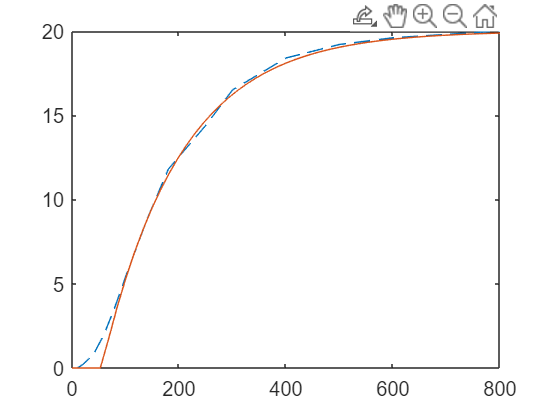

% simulink仿真
out=sim('ex2_2',800);
t0=[0
3.15544362088405e-30
1.00475457260383e-05
6.02852743562299e-05
0.000311473917507188
0.00156741713326198
0.00784713321203593
0.0392457136059057
0.196238615575254
0.981203125421998
4.90602567465572
20.9060256746557
36.9060256746557
52.9060256746557
68.9060256746557
84.9060256746557
100.906025674656
116.906025674656
132.906025674656
148.906025674656
164.906025674656
180.906025674656
196.906025674656
212.906025674656
228.906025674656
244.906025674656
260.906025674656
276.906025674656
292.906025674656
308.906025674656
324.906025674656
340.906025674656
356.906025674656
372.906025674656
388.906025674656
404.906025674656
420.906025674656
436.906025674656
452.906025674656
468.906025674656
484.906025674656
500.906025674656
516.906025674656
532.906025674656
548.906025674656
564.906025674656
580.906025674656
596.906025674656
612.906025674656
628.906025674656
644.906025674656
660.906025674656
676.906025674656
692.906025674656
708.906025674656
724.906025674656
740.906025674656
756.906025674656
772.906025674656
788.906025674656
800];
h0=[0
0
0
0
0
0
0
0
0
0
0
0
0
0
1.78314978080571
3.66669158014038
5.35548348214632
6.86966176546781
8.22728070653398
9.44452784938597
10.5359170175555
11.5144613693679
12.3918285600925
13.1784798610112
13.8837948941913
14.5161834702338
15.0831858624922
15.5915627133815
16.0473756447708
16.4560595336189
16.8224873146273
17.1510280825867
17.4455991871965
17.7097129415106
17.9465185009368
18.1588394121320
18.3492072795081
18.5198919507696
18.6729285814007
18.8101419008033
18.9331679694236
19.0434736862891
19.1423742795508
19.2310489885820
19.3105551246164
19.3818406775796
19.4457556194283
19.5030620387759
19.5544432276411
19.6005118286680
19.6418171399589
19.6788516646201
19.7120569831135
19.7418290184328
19.7685227568841
19.7924564807583
19.8139155633642
19.8331558716717
19.8504068171369
19.8658740910854
19.8756940451816];
plot(t0,h0);

例2-4 计算法 计算用二阶惯性+迟滞拟合的参数

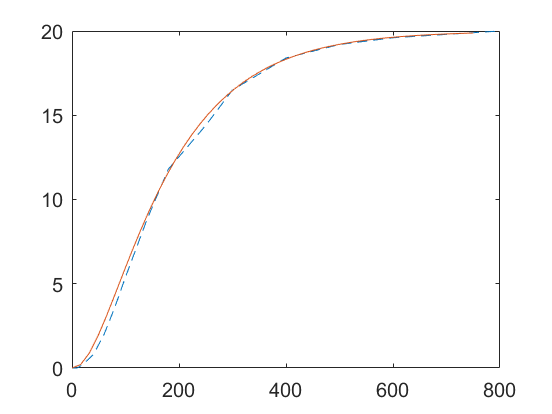

figure;
% 描点
tao=10;
t=[0 10 20 40 60 80 100 140 180 250 300 400 500 600 700 800];
h=[0 0 0.2 0.8 2.0 3.6 5.4 8.8 11.8 14.4 16.5 18.4 19.2 19.6 19.8 20];
hh=h/h(length(h));
plot(t,h,'--');
hold on 
% % 计算法用二阶惯性+迟滞拟合的参数
% h1=0.4;t1=interp1(hh,t,h1)
% h2=0.8;t2=interp1(hh,t,h2)
% if(abs(t1/t2-0.46)<0.01)
%     T1=(t1+t2)/4.36,T2=T1
% else if(t1/t2<0.46)
%     if(abs(t1/2-0.32)<0.01)
%         T1=(t1+t2)/2.12,T2=0
%     else if(t1/2<0.32)
%         T1=(t1+t2)/2.12,T2=0
%     end
%     if(t1/2>0.32)
%         T12=(t1+t2)/2.16;
%         T1T2=(1.74*(t1/t2)-0.55)*T12^2;
%         disp(['T1+T2=',num2str(T12)])
%         disp(['T1*T2=',num2str(T1T2)])
%     end
%     end
% end
%     if(t1/t2>0.46)
%         disp('系统复杂，要用高阶惯性表示');
%     end
% end
% simulink仿真
out1=sim('ex2_2',800);
t0=[0
3.15544362088405e-30
1.00475457260383e-05
6.02852743562299e-05
0.000311473917507188
0.00156741713326198
0.00784713321203593
0.0392457136059057
0.196238615575254
0.981203125421998
4.90602567465572
18.2059372376153
34.2059372376153
50.2059372376153
66.2059372376153
82.2059372376153
98.2059372376153
114.205937237615
130.205937237615
146.205937237615
162.205937237615
178.205937237615
194.205937237615
210.205937237615
226.205937237615
242.205937237615
258.205937237615
274.205937237615
290.205937237615
306.205937237615
322.205937237615
338.205937237615
354.205937237615
370.205937237615
386.205937237615
402.205937237615
418.205937237615
434.205937237615
450.205937237615
466.205937237615
482.205937237615
498.205937237615
514.205937237615
530.205937237615
546.205937237615
562.205937237615
578.205937237615
594.205937237615
610.205937237615
626.205937237615
642.205937237615
658.205937237615
674.205937237615
690.205937237615
706.205937237615
722.205937237615
738.205937237615
754.205937237615
770.205937237615
786.205937237615
800];
h0=[0
0
0
0
0
0
0
0
0
0
0
0
0
0
0.209711415536691
0.881701306273134
1.87752618609012
3.06952317905901
4.35421440498829
5.66117319956354
6.94368570124180
8.17193711342010
9.32805211069239
10.4024956177049
11.3914705020990
12.2950447770956
13.1158116960207
13.8579382738586
14.5264961831757
15.1269972531974
15.6650766140490
16.1462818370509
16.5759376748648
16.9590642703060
17.3003327673169
17.6040467025661
17.8741408093737
18.1141912425842
18.3274329659961
18.5167813041828
18.6848555740356
18.8340033708726
18.9663245577239
19.0836943445747
19.1877850837673
19.2800865754638
19.3619247928786
19.4344790154046
19.4987974093836
19.5558111288431
19.6063470276590
19.6511390843888
19.6908386443956
19.7260235829669
19.7572064894411
19.7848419669523
19.8093331360515
19.8310374236727
19.8502717120416
19.8673169154055
19.8804502854470];
plot(t0,h0);
xlim([0,800])

例2-5 用一阶惯性+迟滞拟合系统

% ex2_5_1 作图法
numo=2.5;
deno=conv([1,1],conv([2,1],[5,1]));
step(numo,deno)

K=2.5

求得τ=1.3s,T=10.5s

% ex2_5_2 计算法
Go=tf(2.5,conv([1,1],conv([2,1],[5,1])));
t=0:0.01:50;
[y,x]=step(Go,t);
K=y(length(y))/1

K = 2.4998

y=y/y(length(y));
[e1,n1]=min(abs(y-0.39));t1=t(n1);
[e2,n2]=min(abs(y-0.63));t2=t(n2);
T=2*(t2-t1),tao=2*t1-t2

T = 5.7600

tao = 2.6100

求得τ=2.61s,T=5.76s

plot(out)